% Clear workspace, command window, and close all figures
clear;
clc;
close all;

% Increase graphics timeout
set(0, 'DefaultFigureCreateFcn', @(fig, ~)set(fig, 'CloseRequestFcn', @(src, ~)close(src)));

# Tuneable Parameters

% Simulation parameters
params.dt = 1;  % time step (s)
num_iterations = 100; % Number of time steps
num_vehicles = 10; % Number of vehicles 

% generate_traffic_signal_states
params.red_time = 20;   % Red light duration (s)
params.yellow_time = 3.5; % Yellow light duration (s)
params.green_time = 20; % Green light duration (s)
params.d_stop_line = 300; % Stop line position (m)

% decision model
params.D_h = 150;       % Decision distance in meters
params.T_reaction = 1.0;% Reaction time in seconds
params.p_stop = 0.7;    % Probability of stopping in the dilemma zone
params.b_max = 3.0; 
params.a = 1.0;

% IDM parameters
params.v_desired = 15;  % desired speed (m/s)
params.a_max = 1.0;     % maximum acceleration (m/s^2)
params.b = 1.5;         % comfortable deceleration (m/s^2)
params.s0 = 2.0;        % minimum gap (m)
params.T = 1.0;         % safe time headway (s)
params.delta = 4;       % acceleration exponent

% Acceleration noise
params.n_a = 0.1;       % Bound for uniform distribution U[-params.n_a, params.n_a]




#  generate_traffic_signal_states

% Generate traffic signal states
[traffic_signal_states] = generate_traffic_signal_states(num_iterations, params)

traffic_signal_states = 100×1 string array
    "green"
    "green"
    "green"
    "green"
    "green"
    "green"
    "green"
    "green"
    "green"
    "green"
    "green"
    "green"
    "green"
    "green"
    "green"
    "green"
    "green"
    "green"
    "green"
    "green"
    "yellow"
    "yellow"
    "yellow"
    "yellow"
    "red"
    "red"
    "red"
    "red"
    "red"
    "red"


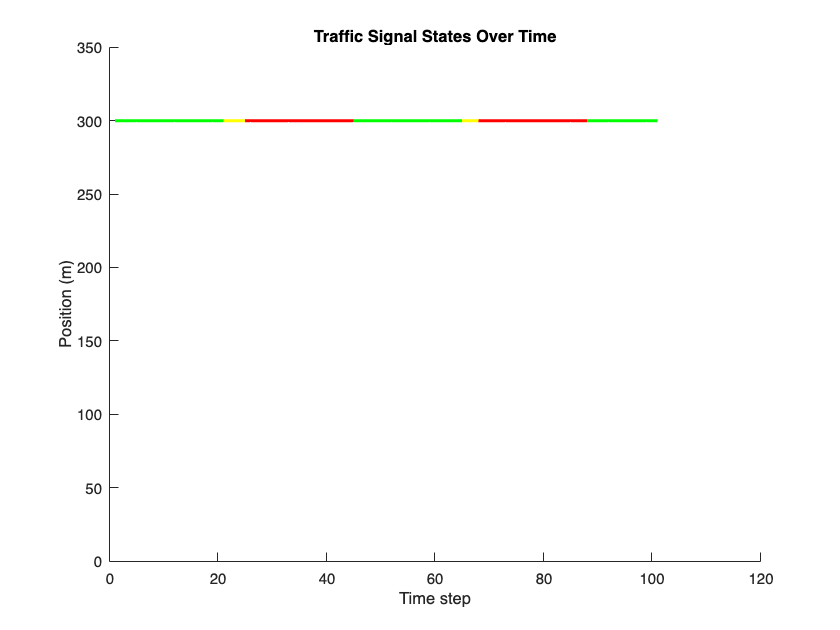

% Plot traffic light state as a horizontal line at y = d_stop_line
figure(1);
hold on;

d_stop_line = params.d_stop_line;

for k = 1:num_iterations
    if traffic_signal_states(k) == "red"
        plot([k k+1], [d_stop_line d_stop_line], 'r', 'LineWidth', 2);
    elseif traffic_signal_states(k) == "yellow"
        plot([k k+1], [d_stop_line d_stop_line], 'y', 'LineWidth', 2);
    elseif traffic_signal_states(k) == "green"
        plot([k k+1], [d_stop_line d_stop_line], 'g', 'LineWidth', 2);
    end
end

xlabel('Time step');
ylabel('Position (m)');
title('Traffic Signal States Over Time');
ylim([0 d_stop_line + 50]);
hold off;

# IDM

% Initial conditions
d = zeros(num_iterations, num_vehicles);
v = zeros(num_iterations, num_vehicles);
a_IDM = zeros(num_iterations, num_vehicles);
s = 20 * ones(1, num_vehicles);  % initial gap to the leading vehicle (m)

% Set initial positions and speeds
d(1, :) = rand(1, num_vehicles) * 100; % Random initial positions (m)
v(1, :) = rand(1, num_vehicles) * 10; % Random initial speeds (m/s)

% Simulate over time
for k = 1:num_iterations-1
    for i = 1:num_vehicles
        if i == 1
            % Leading vehicle dynamics (no vehicle in front)
            delta_v = v(k, i); % Speed difference to leading vehicle, 0 for first vehicle
            s_i = Inf; % Infinite gap for the leading vehicle
        else
            % Following vehicles
            delta_v = v(k, i-1) - v(k, i);
            s_i = d(k, i-1) - d(k, i);
            if s_i <= 0
                s_i = 0.1; % Avoid division by zero or negative gap
            end
        end

         % Ensure delta_v is within reasonable bounds
        delta_v = max(min(delta_v, params.v_desired), -params.v_desired);

        a_IDM(k, i) = intelligent_driver_model(v(k, i), delta_v, s_i, params);

        % Update velocity and position using state_transition function
        current_state = [d(k, i), v(k, i), a_IDM(k, i), 0, 0]; % Assuming D and lane are not used in the current context
        next_state = state_transition(current_state, params);
        
        % Extract next state's position and velocity
        d(k+1, i) = next_state(1);
        v(k+1, i) = next_state(2);

        % Ensure velocities and positions are within reasonable bounds
        v(k+1, i) = max(min(v(k+1, i), 2 * params.v_desired), 0); % Speed cannot be negative
        d(k+1, i) = max(d(k+1, i), 0); % Position cannot be negative

        % Check for invalid values
        if isnan(d(k+1, i)) || isnan(v(k+1, i)) || isinf(d(k+1, i)) || isinf(v(k+1, i))
            error('Invalid value detected at iteration %d for vehicle %d.', k, i);
        end
    end
end
% Display results
disp('Accelerations (a_IDM):');

Accelerations (a_IDM):


disp(a_IDM);

    0.9996    0.9938   -1.5000   -1.5000    0.9595   -1.5000    0.9939   -1.5000   -1.5000    0.8240
    0.9982    0.9889   -1.5000   -1.5000   -0.5001    0.9118    0.9948   -1.5000   -1.5000    0.6318
    0.9945    0.9803   -1.5000   -1.5000   -1.5000    0.8540    0.9922   -1.5000   -1.5000    0.2655
    0.9868    0.9660   -1.5000   -0.3911   -1.5000    0.8535    0.9878   -1.5000   -1.5000   -0.3399
    0.9732    0.9441   -1.5000    0.6306   -1.5000    0.8844    0.9803   -1.5000   -1.5000   -1.5000
    0.9514    0.9124   -1.5000   -0.8714   -1.5000    0.9487    0.9672    0.7738   -1.5000   -1.5000
    0.9193    0.8692   -1.5000   -1.5000   -1.5000    0.9484    0.9455    0.7948   -1.5000   -1.5000
    0.8753    0.8136   -1.5000   -1.5000   -1.5000   -1.5000    0.9132    0.7938   -1.5000   -1.5000
    0.8186    0.7460    0.9756   -1.5000   -1.5000   -1.5000    0.8371    0.7923   -1.5000   -1.5000
    0.7499    0.6682    0.9061    0.7787   -1.5000   -1.5000   -0.3213    0.7912   -1.5000 

disp('Velocities (v):');

Velocities (v):


disp(v);

    2.0911    2.7247    7.7582    3.3141    6.0307    1.8401    0.8746    3.0892    2.3088    9.0919
    3.0908    3.7185    6.2582    1.8141    6.9903    0.3401    1.8685    1.5892    0.8088    9.9159
    4.0890    4.7074    4.7582    0.3141    6.4901    1.2519    2.8634    0.0892         0   10.5476
    5.0834    5.6877    3.2582         0    4.9901    2.1059    3.8555         0         0   10.8131
    6.0702    6.6537    1.7582         0    3.4901    2.9594    4.8433         0         0   10.4733
    7.0434    7.5978    0.2582    0.6306    1.9901    3.8438    5.8236         0         0    8.9733
    7.9948    8.5102         0         0    0.4901    4.7925    6.7909    0.7738         0    7.4733
    8.9141    9.3794         0         0         0    5.7409    7.7364    1.5686         0    5.9733
    9.7894   10.1931         0         0         0    4.2409    8.6496    2.3624         0    4.4733
   10.6080   10.9391    0.9756         0         0    2.7409    9.4867    3.1547         0 

disp('Positions (d):');

Positions (d):


disp(d);

   1.0e+03 *

    0.0828    0.0264    0.0677    0.0794    0.0682    0.0651    0.0237    0.0477    0.0936    0.0241
    0.0863    0.0306    0.0733    0.0805    0.0757    0.0647    0.0261    0.0486    0.0937    0.0344
    0.0909    0.0358    0.0773    0.0800    0.0819    0.0664    0.0295    0.0479    0.0923    0.0453
    0.0965    0.0420    0.0798    0.0781    0.0861    0.0689    0.0338    0.0458    0.0900    0.0562
    0.1031    0.0492    0.0808    0.0775    0.0889    0.0723    0.0391    0.0435    0.0878    0.0666
    0.1106    0.0572    0.0803    0.0784    0.0901    0.0766    0.0455    0.0413    0.0855    0.0748
    0.1191    0.0662    0.0783    0.0778    0.0899    0.0818    0.0527    0.0424    0.0833    0.0815
    0.1285    0.0760    0.0760    0.0755    0.0881    0.0881    0.0609    0.0444    0.0810    0.0867
    0.1387    0.0866    0.0738    0.0733    0.0858    0.0916    0.0701    0.0471    0.0788    0.0904
    0.1497    0.0979    0.0753    0.0710    0.0836    0.0935    0.0800    0.0

# decision

% Initialize states
d = zeros(num_iterations, num_vehicles);
v = zeros(num_iterations, num_vehicles);
T_elapsed = zeros(num_iterations, num_vehicles);
D = strings(num_iterations, num_vehicles);
S = strings(num_iterations, 1);

% Initial positions and speeds
d(1, :) = rand(1, num_vehicles) * 100; % Random initial positions
v(1, :) = rand(1, num_vehicles) * 10; % Random initial speeds

% Generate traffic signal states
[traffic_signal_states] = generate_traffic_signal_states(num_iterations, params);
S(:, 1) = traffic_signal_states;

% Simulate over time
for k = 1:num_iterations-1
    % Simulate vehicle positions and speeds (simple linear model for example)
    d(k+1, :) = d(k, :) + v(k, :);
    v(k+1, :) = v(k, :) + (rand(1, num_vehicles) - 0.5); % Random acceleration
    
    % Calculate decisions
    D(k+1, :) = decision_making(d(k, :), d(k+1, :), v(k, :), v(k+1, :), S(k), S(k+1), T_elapsed(k, :), T_elapsed(k+1, :), D(k, :), params);
end

Error: File: decision_making.mlx Line: 62 Column: 5
Illegal use of reserved keyword "end".


% Plot results
figure(3);
hold on;
colors = {'r', 'g', 'b', 'c', 'm', 'y', 'k', [0.5 0.5 0.5], [0.8 0.2 0.2], [0.2 0.8 0.2]};

for i = 1:num_vehicles
    for k = 1:num_iterations
        if D(k, i) == "stop"
            plot(k, i, 's', 'Color', colors{i}, 'MarkerFaceColor', 'r'); % Red square for stop
        elseif D(k, i) == "go"
            plot(k, i, 'o', 'Color', colors{i}, 'MarkerFaceColor', 'g'); % Green circle for go
        else
            plot(k, i, '*', 'Color', colors{i}); % Star for undecided or other states
        end
    end
end

xlabel('Time step');
ylabel('Vehicle index');
title('Vehicle Decisions Over Time');
hold off;